clear all;close all;

mo=load(['C:\Users\sgrc-325\Desktop\git\pipes\data\1118_1.CSV']); %DOHZ 4hz*2 0.7m high 2m、2mside blank、40、70、90cm/s iron pipe test run


moo=mo;
mo=moo(:,[1:17]);
% mo(1,:)=[];

[No,~]=size(moo);
t0=[1 No];
t=moo(:,1);
[a1 a3]=size(moo);
[a1 a2]=size(mo);
f=moo(:,a3); %freqency
mo_cor=zeros(a1,a2);
% mo_cor=mo;

% mo(a1-200:a1,:)=[];
t=mo(:,1);

% mo_cor(:,1)=mo(:,1);
% for i=1:a1   %校正數據
%     mo_cor(i,2:4)=(Ta*Ka*(mo(i,2:4)'+Ba))';
%     mo_cor(i,5:7)=(Tg*Kg*(mo(i,5:7)'+Bg))';
%     mo_cor(i,8:10)=(Tm2a*(mo(i,8:10)'+Bm))';
%     mo_cor(i,11:13)=(Tm2a_2*(mo(i,11:13)'+Bm_2))';
% end

% acc1 = mo_cor(:,2:4);  %有校正
% gyr=mo_cor(:,5:7);
% % acc2 = mo_cor(:,5:7);
% m = mo_cor(:,8:10)*0.01;   %%%% to guess
% m2 = mo_cor(:,11:13)*0.01;   %%%%

acc1 = mo(:,3:5);  %無校正
acc2 = mo(:,6:8);  %無校正
gyr1=mo(:,9:11);
gyr2=mo(:,12:14);
m = mo(:,15:17); %%%% to guess
temp=moo(:,20:23);
h1=moo(:,18);
h2=moo(:,19);
magt=moo(:,20);
imu1t=moo(:,21);
imu2t=moo(:,22);
mcut=moo(:,23);
f=moo(:,24);
delay=moo(:,25);
ax1=acc1(:,1);ay1=acc1(:,2);az1=acc1(:,3);
ax2=acc2(:,1);ay2=acc2(:,2);az2=acc2(:,3);
aGo=sqrt(mo_cor(:,2).^2+mo_cor(:,3).^2+mo_cor(:,4).^2);
aG=sqrt(ax1.^2+ay1.^2+az1.^2);
aG2=sqrt(ax2.^2+ay2.^2+az2.^2);
GG=sqrt(gyr1(:,1).^2+gyr1(:,2).^2+gyr1(:,3).^2)*0.01;
GG2=sqrt(gyr2(:,1).^2+gyr2(:,2).^2+gyr2(:,3).^2)*0.01;
mm4=sqrt(m(:,1).^2+m(:,2).^2+m(:,3).^2);
% mm42=sqrt(m2(:,1).^2+m2(:,2).^2+m2(:,3).^2);
stdd=std(mo)'; %看標準差
stdd_cor=std(mo_cor)';

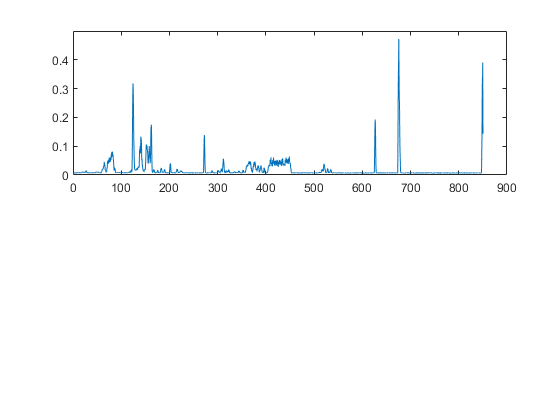

close all
figure(1)
subplot(2,1,1)
plot(t,smooth(GG,200))

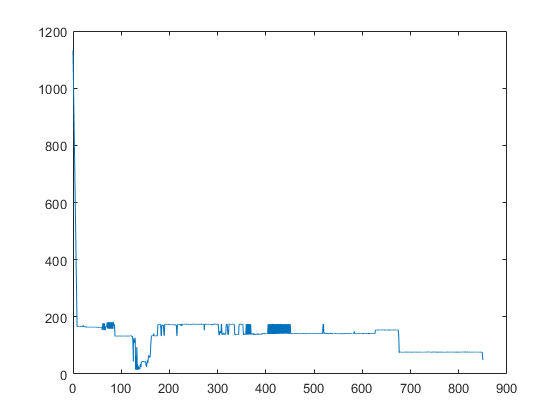


figure(2)
plot(t,mm4)

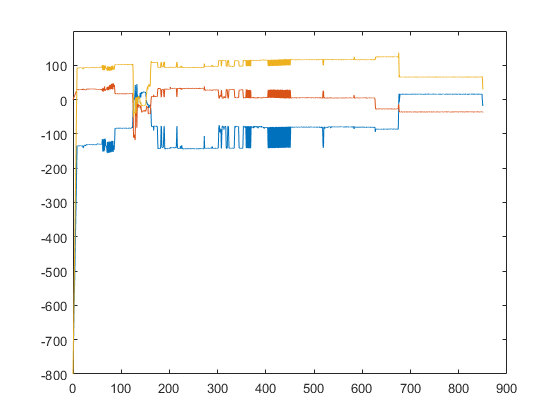


figure(3)
plot(t,m)

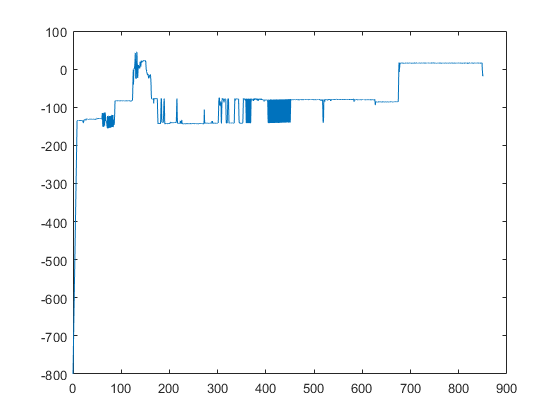

% hold on
% plot(t,m(:,1)+500)
% plot(t,m(:,2)-100)
% plot(t,m(:,3)-500)
% hold off

figure(4)
plot(t,m(:,1))

% plot(t,m(:,2))
% plot(t,m(:,3))


close all
rs=398;
re=460;
[~,rs]=min(abs(t-rs));
[~,re]=min(abs(t-re));

rt=t(rs:re,:);
rdata1=acc1(rs:re,:);
rdata2=acc2(rs:re,:);

[rn,~]=size(rdata1);


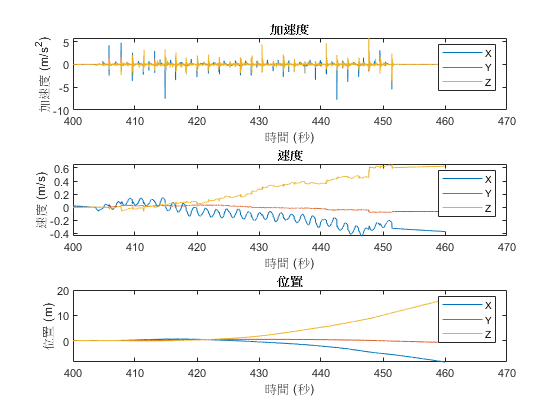

close all %無濾波

% 假設 rdata1 是包含三軸加速度的陣列，第一列是時間，後三列是加速度數據
time = rt;  % 時間陣列 (秒)
accel = rdata1;  % 三軸加速度數據 (m/s^2)

% 將加速度數據中心化 (減去平均值以去除偏移)
accel_centered = accel - mean(accel(1:500,:));

% 計算速度 (積分加速度)
velocity = cumtrapz(time, accel_centered);

% 將速度中心化 (處理累積誤差)
velocity_centered = velocity - mean(velocity(1:500,:));

% 計算位置 (積分速度)
position = cumtrapz(time, velocity_centered);

% 可視化結果
figure;
subplot(3, 1, 1);
plot(time, accel_centered);
title('加速度');
xlabel('時間 (秒)');
ylabel('加速度 (m/s^2)');
legend('X', 'Y', 'Z');

subplot(3, 1, 2);
plot(time, velocity_centered);
title('速度');
xlabel('時間 (秒)');
ylabel('速度 (m/s)');
legend('X', 'Y', 'Z');

subplot(3, 1, 3);
plot(time, position);
title('位置');
xlabel('時間 (秒)');
ylabel('位置 (m)');
legend('X', 'Y', 'Z');

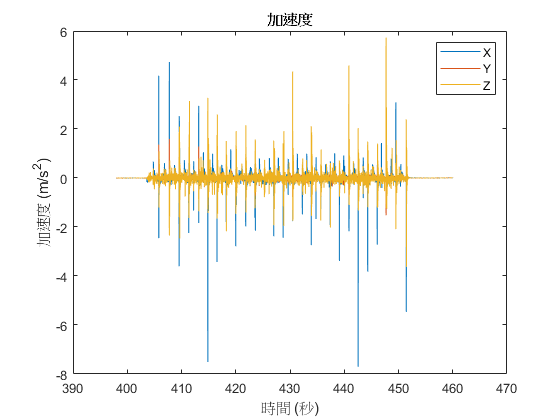

close all

% 假設 rdata1 是包含三軸加速度的陣列，第一列是時間，後三列是加速度數據
time = rt;  % 時間陣列 (秒)
accel = rdata1;  % 三軸加速度數據 (m/s^2)

% 將加速度數據中心化 (減去初始穩定段的平均值)
accel_centered = accel - mean(accel(1:500, :));

% 高通濾波去除低頻飄移 (假設運動頻率 > 0.1 Hz)
Fs = 1 / mean(diff(time));  % 取樣頻率
fc = 0.1;  % 高通濾波截止頻率 (Hz)
[b, a] = butter(1, fc / (Fs / 2), 'high');  % 一階高通濾波器
accel_filtered = filtfilt(b, a, accel_centered);  % 雙向濾波
% accel_filtered = accel_centered;  % 雙向濾波

% 計算速度 (積分加速度)
velocity = cumtrapz(time, accel_filtered);

% 找到速度零點並修正飄移
velocity_corrected = velocity;
for i = 2:length(velocity) - 1
    if all(abs(velocity(i, :)) < 0.01)  % 假設速度零點閾值
        velocity_corrected(i:end, :) = velocity_corrected(i:end, :) - velocity_corrected(i, :);
    end
end

% 計算位置 (積分速度)
position = cumtrapz(time, velocity_corrected);

% 修正位置飄移 (將每段運動的終點對齊)
for i = 2:length(position) - 1
    if all(abs(velocity_corrected(i, :)) < 0.01)  % 假設速度零點閾值
        position(i:end, :) = position(i:end, :) - position(i, :);
    end
end

% 可視化結果
figure(1)
plot(time, accel_filtered);
title('加速度');
xlabel('時間 (秒)');
ylabel('加速度 (m/s^2)');
legend('X', 'Y', 'Z');

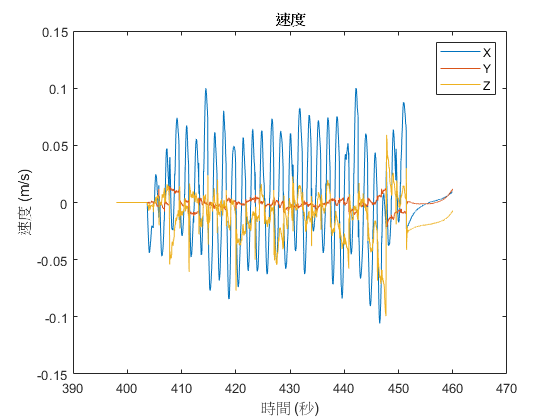


figure(2)
plot(time, velocity_corrected);
title('速度');
xlabel('時間 (秒)');
ylabel('速度 (m/s)');
legend('X', 'Y', 'Z');

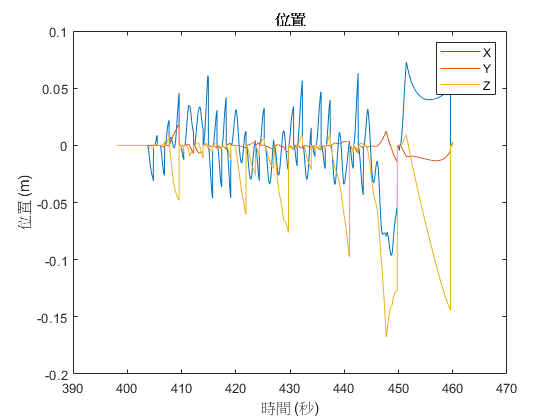


figure(3)
plot(time, position);
title('位置');
xlabel('時間 (秒)');
ylabel('位置 (m)');
legend('X', 'Y', 'Z');